           Положительный заряд *q *равномерно распределен по объему шара радиуса *а*. Определить напряженность электрического поля, электрическую индукцию и скалярный потенциал внутри и вне шара. Диэлектрическая проницаемость материала *ε**а1*, окружающей  среды *ε**а2*. Построить зависимости *E(r), D(r), ****(r), *указать характерные особенности графиков и причину их появления. Провести проверку граничных условий на границе раздела сред. Исходные данные: *a*[мм] = M+2N; *q*[Кл] = 0,05·N; *ε**а *= *ε**0**ε**r*; *ε**r1 *= 2*+*N/10; *ε**r2 *= 1. 

- **КОНСТАНТЫ**

E0 = 8.85e-12

E0 = 8.8500e-12

- **ДАНО**

M = 5; N = 12;
Ea1 = E0 * (2 + N/10)

Ea1 = 2.8320e-11

Ea2 = E0

Ea2 = 8.8500e-12

a = (M + 2*N)*1e-3 % R

a = 0.0290

q = 0.05 * N

q = 0.6000

Ea = E0 * Ea1

Ea = 2.5063e-22

- **НАЙТИ**


$$\begin{array}{l}
\varphi =?\\
D=?\\
E=?
\end{array}$$


- **РЕШЕНИЕ**

R = a. Так как у нас есть две разные среды, то для начала обозначим *k *в зависимости от r*,*

 $k=\frac{1}{4\pi \varepsilon_0 }$при r > R, $k=\frac{1}{4\pi {\varepsilon \varepsilon }_0 }$при r < R

Дальше в решении будем учитывать просто k, который припостроении графиков надо будет учесть, по зависимости, которая обозначена выше. Найдем для начала напряженность электрического поля и скалярный потенциал внутри и вне шара. Применим теорему Гаусса. Выберем в качестве замкнутый шар радиуса r > R (рис.). Очевидно, что напряженность наповерхности этого шара будет одинакова по величине и направлена по радиусу. Тогда поток напряженности через него будет $E*4\pi r^2$. Согласно теореме Гаусса

 $E*4\pi r^2 =4\pi \textrm{kq}$ , 

откуда следует $E\left(r\right)=k\frac{q}{r^2 }$ . Вне шара напряженность поля совпадает с напряженностью заряда, находящегося вцентре, то и потенциал при r > R выразится в виде

 $\varphi \left(r\right)=k\frac{q}{r}$ . 

Чтобы найти напряженность электрического поля внутри шара, выберем вкачестве замкнутой поверхности сферу радиуса r < R с центром в центре шара.Из симметрии ясно, что напряженность поля направлена по радиусу иодинакова по величине на всей поверхности сферы. Из теоремы Гауссаследует $E\left(r\right)*4\pi r^2 =4\pi \textrm{kq}\left(r\right)$ , 

где q(r) – заряд внутри выбранной поверхности. Введем плотность заряда шара ρ. Тогда 

$q\left(r\right)=\rho \frac{4}{3}\pi r^3$ и $E\left(r\right)=k\frac{q\left(r\right)}{r^2 }=$$\frac{4}{3}k\rho \pi r$ . 

Плотность заряда равна полному заряду, деленному на объем шара

 $\rho =\frac{3q}{4\pi R^3 }$ . 

Для напряженности поля внутри шара получим

 $E=k\frac{q}{R^3 }r$.  

Найдем потенциал внутри шара

 $\varphi \left(r\right)=-\int_{\infty }^R k\frac{q}{r^2 }\textrm{dr}-\int_R^r k\frac{q}{R^3 }\textrm{rdr}\;$ . 

Первый интеграл имеет смысл работы по переносу единичного положительногозаряда из бесконечности до поверхности шара и равен $\frac{\textrm{kq}}{R}$. Второй член будет равен $-\int_R^r k\frac{q}{R^3 }\textrm{rdr}\;=-k\frac{q}{R^3 }\frac{r^2 }{2}+k\frac{{\textrm{qr}}^2 }{2R^3 }$. Значение потенциала внутри шара определится выражением 

$\varphi \left(r\right)=\frac{3}{2}k\frac{q}{R}-k\frac{{\textrm{qr}}^2 }{2R^3 }$. 

И так подведем итог напряженность электрического поля и скалярный потенциал внутри и вне шара.

$E=k\frac{q}{r^2 }\;$при r > R, $E=k\frac{q}{R^3 }r$ при r < R , и

$\varphi =k\frac{q}{r}$ при r > R, $\varphi =\frac{3}{2}k\frac{q}{R}-k\frac{{\textrm{qr}}^2 }{2R^3 }$ при r < R 

Теперь найдем электрическую индукцию 


$$D=\varepsilon_0 E+P=\varepsilon_0 E+\kappa \varepsilon_0 E=\varepsilon_0 \left(1+\kappa \right)E=\varepsilon_0 \varepsilon E$$


Тогда 

$D=\varepsilon_0 E$ при r > R, $D=\varepsilon_0 \varepsilon E$ при r < R.

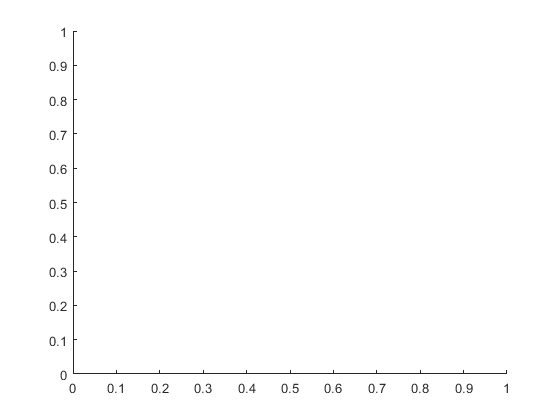

cla reset;


% [E, r] = E_graph(Ea1, Ea2, q, a, 1);
% plot(r, E, "Color","blue");
% hold on;
% plot([a a], [0 6.7e12], '--');
% hold off;
% xlabel("r, мм"); 
% ylabel("E, В/м"); 
% title("E(r)");  
% text(a,1e11,'a', 'Color','red'); 
% grid on;
% saveas(gcf, "E_gr_true.png") 

% [Phi, r] = phi_graph(Ea1, Ea2, q, a, 1);
% plot(r, Phi, "Color","blue");
% hold on;
% plot([a a], [0 1.9e11], '--');
% hold off;
% xlabel("r, мм");
% ylabel("Phi, В");
% title("Phi(r)");
% text(a, 0.55e11,'a', 'Color','red');
% grid on;
% saveas(gcf, "Phi_gr_true.png")

% [D, r] = D_graph(Ea1, Ea2, q, a, 1);  
% plot(r, D, 'Color','blue');
% hold on;
% plot([a a], [0 59], '--');
% hold off;
% xlabel("r, мм");
% ylabel("D, Кл/м^2");
% title("D(r)");
% text(a, 20,'a', 'Color','red');
% grid on;
% saveas(gcf, "D_gr_true.png")

$E=k\frac{q}{r^2 }\;$при r > R, $E=k\frac{q}{R^3 }r$ при r < R 

function [E, r] = E_graph(Ea1, Ea2, q, a, n)
    r = linspace(0, 0.1, 1001);
    E = zeros(1, 1001); 
    k1 = 1/(4*pi*Ea1);
    k2 = 1/(4*pi*Ea2);
    for v = 0.0:0.0001:0.1
        if v <= a
            E(n) = (k1*q*v)/(a^3); 
            n = n + 1;
        else
            E(n) = (k2*q)/(v^2);
            n = n + 1;
        end
    end 
end

$\varphi =k\frac{q}{r}$ при r > R, $\varphi =\frac{3}{2}k\frac{q}{R}-k\frac{{\textrm{qr}}^2 }{2R^3 }$ при r < R 

function [Phi, r] = phi_graph(Ea1, Ea2, q, a, n)
    r = linspace(0, 0.1, 1001);
    Phi = zeros(1, 1001);
    k1 = 1/(4*pi*Ea1);
    k2 = 1/(4*pi*Ea2);
    Po = (k1*q)/(2*a);
    for v = 0.0:0.0001:0.1
        if v <= a
            Phi(n) =  Po*(3 - ((v^2)/(a^2)));
            n = n + 1;
        else 
            Phi(n) = (k2*q)/v;
            n = n + 1;
        end
    end
end

$D=\varepsilon_0 E$ при r > R, $D=\varepsilon_0 \varepsilon E$ при r < R

function [D, r] = D_graph(Ea1, Ea2, q, a, n)   
    [E, r] = E_graph(Ea1, Ea2, q, a, 1);
    D = zeros(1, 1001); 
    for v = 0.0:0.0001:0.1
        if v <= a
            D(n) = Ea1*E(n); 
            n = n + 1;
        else
            D(n) = Ea2*E(n);
            n = n + 1;
        end
    end 
end